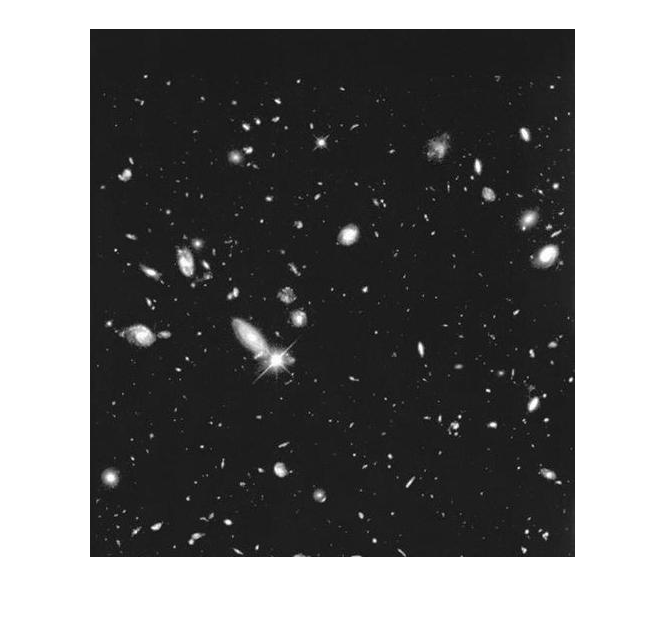

img = double(im2gray(imread("Fig0334(a)(hubble-original).tif")));
imshow(img, []);

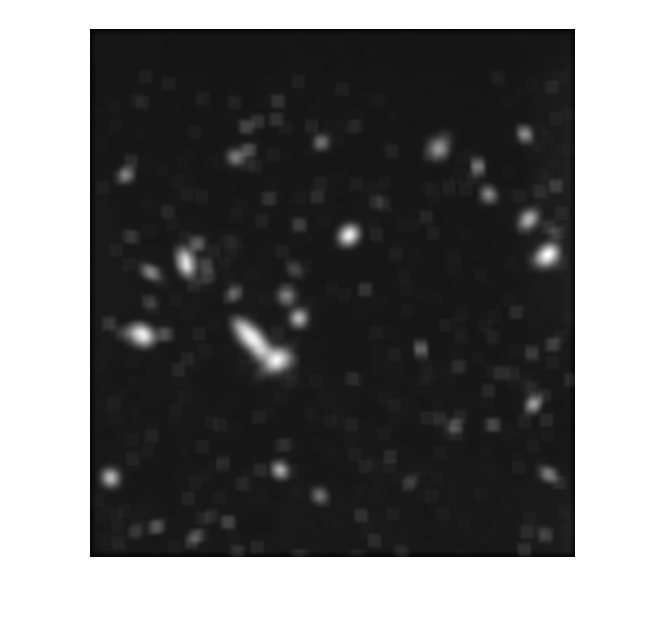

kernelSize = [13, 13];
kernel = ones(kernelSize) ./ (kernelSize(1)*kernelSize(2));
filtered=imfilter(img, kernel);
imshow(filtered, []);

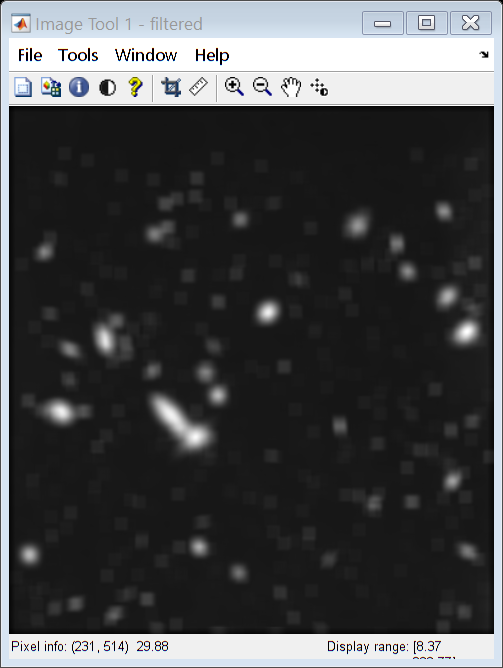

imtool(filtered, []);

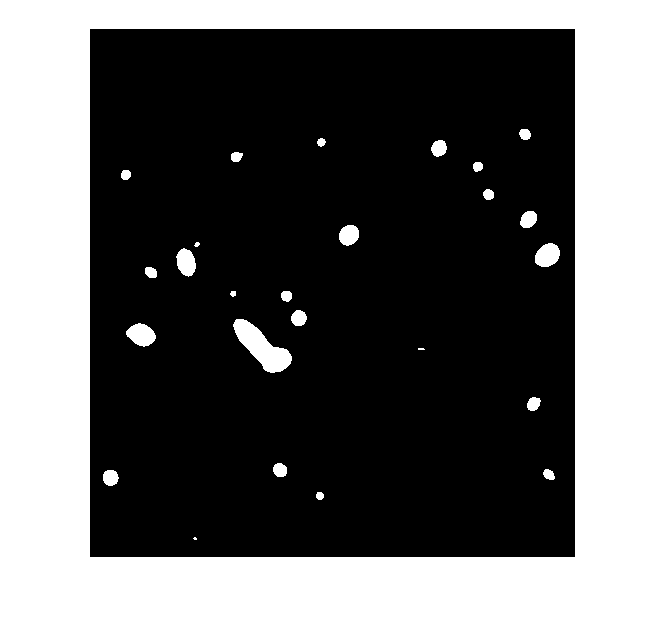

threshold = 90;
binarized = imbinarize(filtered, threshold);
imshow(binarized,[]);

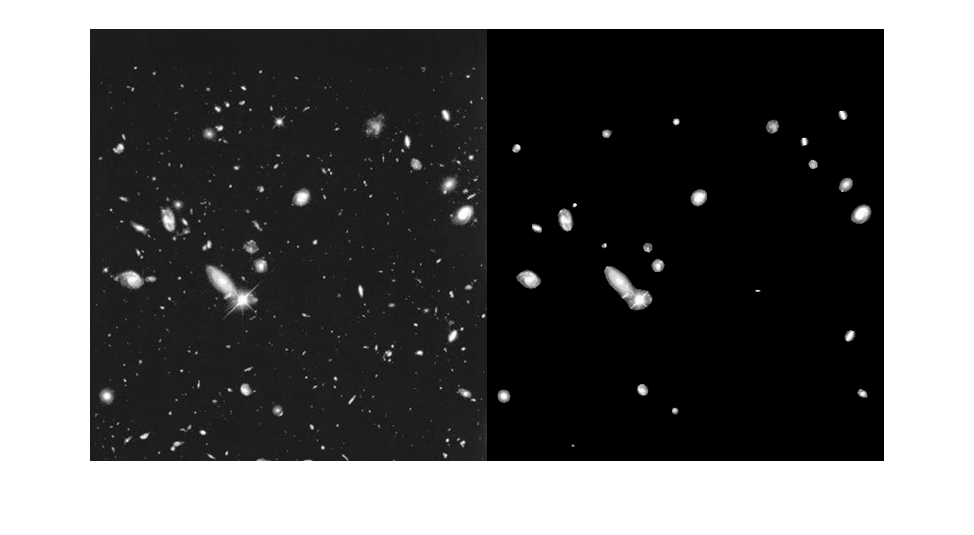

maskedImg = img.*binarized;
montage({uint8(img), uint8(maskedImg)})